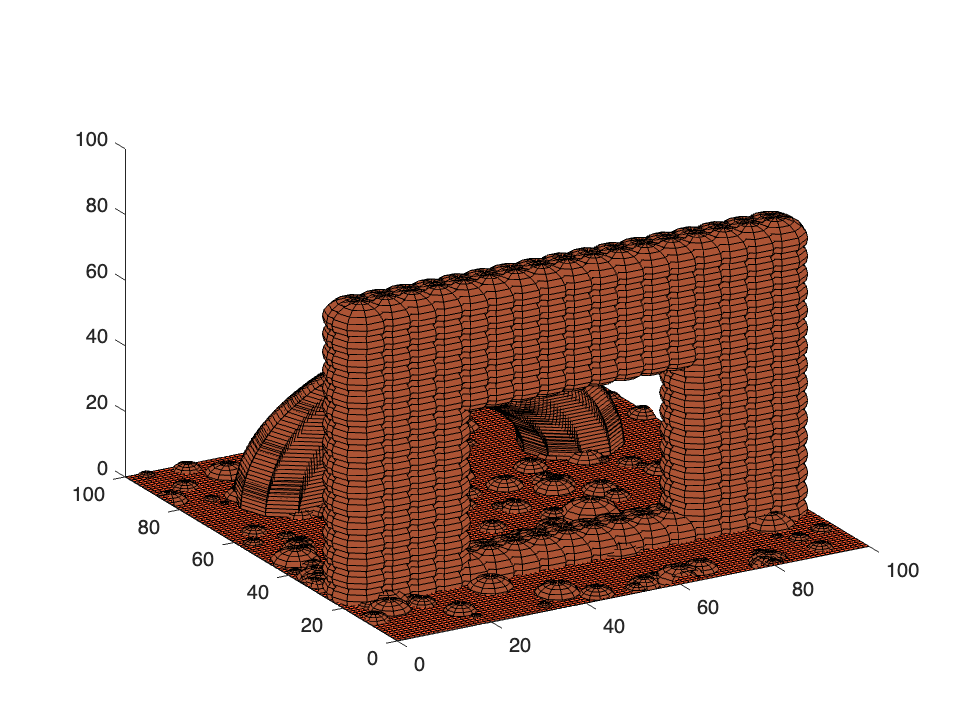

% Script to test picking the standard deviation based on the properties of
% the sample plane

% Create a test world

space = world(100, 100, 100, Obstacle.empty);
space = add_arch(space, [50 75 0], 30, 80, 10);
space = add_terrain(space, 150, 3);
% space = add_wall(space, 20, 80, 40, 50, -10, 60, 6);
space = add_holy_wall(space, 0, 100, 20, 30, -10, 90, 6, [50 20 30], 25);
plot_world(space);

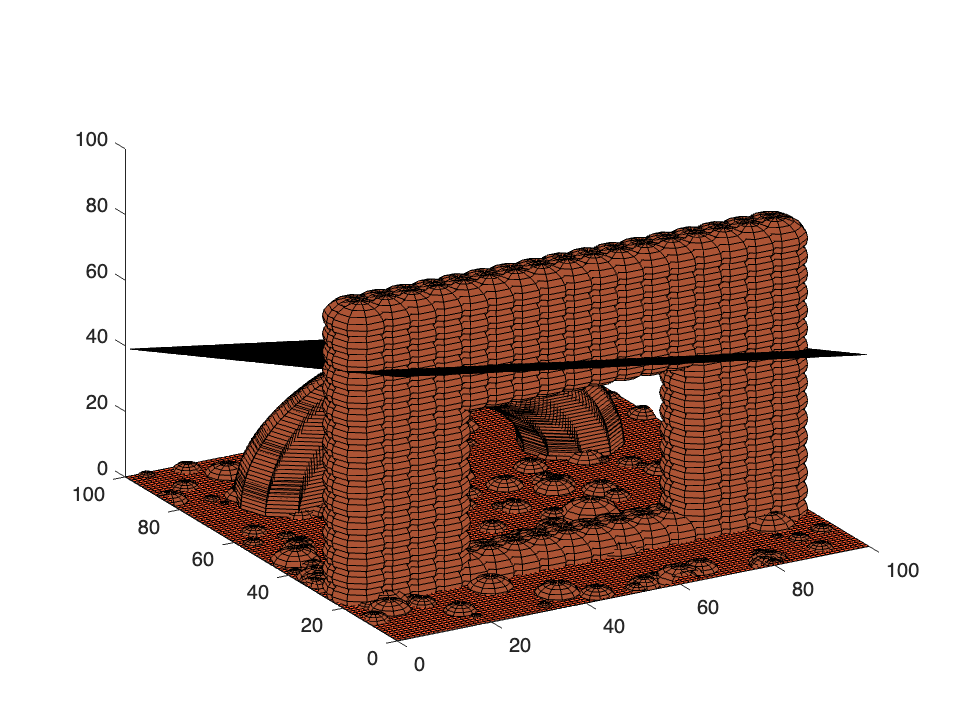


% Create a PRM
planner = PRM(200, 10, space, 5);

% Define the start and goal
start = [45 1 70];
goal = [95 95 20];

% Run the adaptive sampler once to get the sample plane
a_sampled = adaptive_sampler(planner, start, goal, 1);
hold off;

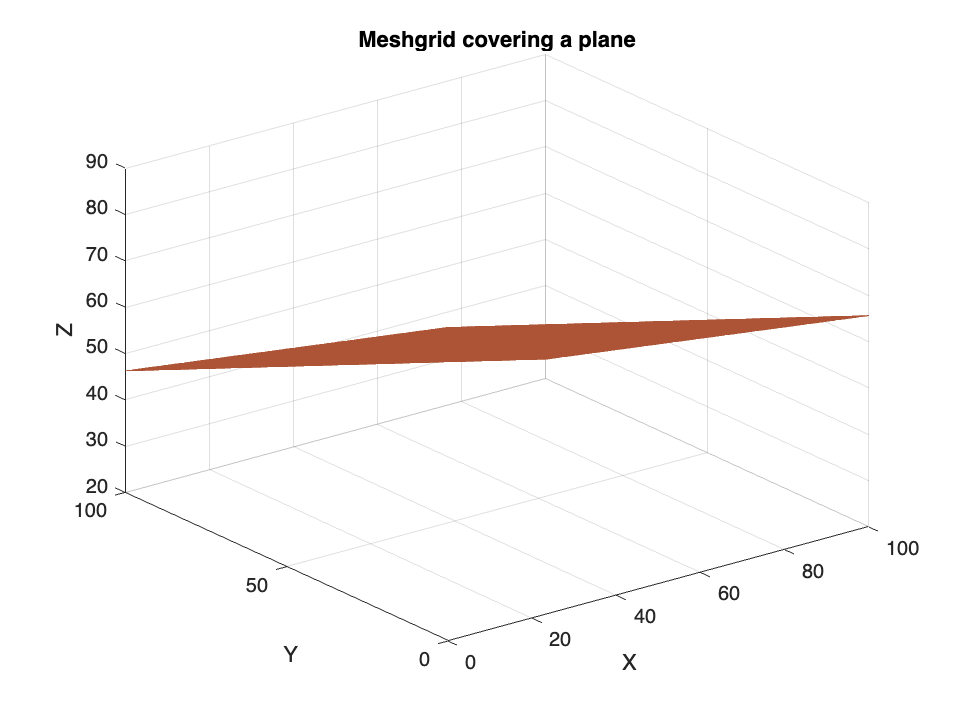

N = a_sampled.pl_norm;

% Define range of values for x and y
x_range = linspace(0, a_sampled.space.xmax, 100); % Range for x
y_range = linspace(0, a_sampled.space.ymax, 100); % Range for y

% Create meshgrid for x and y
[x, y] = meshgrid(x_range, y_range);

% Calculate z values using the plane equation
z = (-N(1)*(x - start(1)) - N(2)*(y - start(2)) + start(3)) / N(3);

% Plot the meshgrid
mesh(x, y, z);
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Meshgrid covering a plane');


% Determine if all points in the meshgrid are in freespace
free = zeros(1, length(x));
for i=1:length(x)
    free(1, i) = in_freespace(space, [x(1, i) y(i, 1) z(i, 1)], 5);
end

total_coll = sum(free(:));
perc_occ = total_coll / length(x);
disp(perc_occ);

    0.7600




max_std_dev = max([space.xmax space.ymax space.zmax]) / 4;
std_dev = max_std_dev * perc_occ;
disp(std_dev);

    19

